# MATH2089 Week 7

This week we examine *hypothesis testing*—a method to test assumptions about model parameters. We begin by assuming that our data is sampled from a parameterised distribution $F_{\theta}$, where $\theta\in\Theta$. The basis of hypothesis testing is to examine the probability that our data comes from some assumed parameter subset $\Theta_{0}\subset\Theta$. For example, we want to test the assumption that the average height of an Australian male $\mu$ is smaller than 1.8m. In order to test this hypothesis, we need to compute a *test statistic* and examine the probability of the observed test statistic under our hypothesis. Our conclusion will depend on the probability of our observed test statistic. Hypothesis tests are quite procedural and follow this structure

- State the parameter

- State the null (assumed) and alternative (complementary) hypotheses

- Construct the test statistic for the parameter

- Identfy the distribution of the test statistic assuming that the null hypothesis is true

- Compute the observed test statistic and it's associated p-value

- Draw your conclusion for a given confidence level

We can think of hypothesis tests functioning similar to criminal court cases. We assume that the defendant is innocent—the null hypothesis—and collect evidence for their guilt—the sample data. If the probability of the guilty evidence—the p-value—is sufficiently small, then it is unlikely that the person is innocent. The tolerance for *sufficiently small* is a matter of choice, however, we conventionally set our *Type 1 error rate* to be $\alpha = 0.05$. This means that 5% of the time we will convict an innocent person, simply due to the randomness of the data.

## Question 1

The manufacturing process specifies that the wafers should be 1 $\mu m$ thick on average. We wish to examine if the manufacturing process has deviated from this specification. We collect $n = 10$ measurements to test this. 

thickness = [0.940, 0.985, 0.986, 0.936, 0.999, 1.089, 0.949, 1.007, 0.947, 0.963];
n = length(thickness);
thicknessAverage = mean(thickness)

thicknessAverage = 0.9801

The sample mean is close to $1\mu m$, which gives some indication that the true population mean is *not different *from $1\mu m$. However, we only have 10 measurements, so it is not enough to make an assessment from the data itself. Let's perform a formal hypothesis test. We start by testing distributional assumptions. 

- Firstly, we need the data to be independent. We cannot make this assertion without understanding the experimental design, but it is a reasonable assumption to make here. 

- We also need the sample mean $\overline{X}$ to be Normally distributed. We cannot apply the Central Limit Theorem since we only have $n = 10$ data points—which does not meet the heuristic of $n$>30. However, if the underlying data are Normally distributed, then the sample mean will also be Normally distributed.

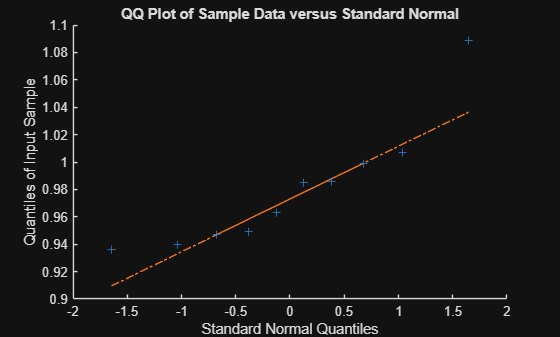

qqplot(thickness)

There are clearly two outliers in this data set in the lower and upper tails, however most of the data appears to be Normally distributed. For our purposes, we shall assume that the data are Normally distributed, thus implying that the sample mean is also Normally distributed. 

We assume that the mean wafer thickness $\mu = 1$ and want to test its deviation otherwise. Hence, our null and alternative hypotheses are respectively

$H_{0}:\mu = 1$and $H_{1}:\mu\neq 1$.

Recall that the alternative hypothesis is the *complement* of the null hypothesis. We use the test statistic

$T = \frac{\overline{X} - 1}{S / \sqrt{n}}$,

where we note that if $\overline{X}\sim N(1,\sigma)$, then $T\sim t_{n - 1}$. We can automate the hypothesis test process using `ttest()`. 

mu_0 = 1; % the assumed value for mu

% h: conclusion of hypothesis test. h = 1 means reject null
% p: p-value of hypothesis test
% ci: confidence interval (default 95% confidence level)
% stats: sample statistics used to compute the p-value
[h, p, ci, stats] = ttest(thickness, mu_0);

[h, p]

ans =          0    0.2030


Our observed p-value is 0.2030, which means that we would see a deviation of this size—or worse—about 1 in 5 times if $\mu = 1$. This certainly does not pass the threshold of 0.05 (1 in 20), and so we have insufficient evidence to suggest that our initial assumption $\mu = 1$ is false. Note that this does not mean that $H_{0}$ is true, only that we don't have enough evidence to negate its assumption. 

We can also apply different siginificance levels by writing `ttest(thickness, mu_0, "Alpha", alpha)` for particular `alpha`. We can also perform the computation manually, instead of using `ttest()`.

thicknessStd = std(thickness);

observedTestStatistic = (thicknessAverage - mu_0) / thicknessStd * sqrt(n)

observedTestStatistic = -1.3730

stats.tstat % observed test statistic via ttest()

ans = -1.3730


2 * tcdf(abs(observedTestStatistic), n - 1, 'upper')

ans = 0.2030

p

p = 0.2030

Note that we have a two-sided alternative hypothesis and hence $p = 2\mathbb{P}(T > \vert t_{\text{obs}}\vert)$. We can also draw an equivalent conclusion using the confidence interval. If the confidence interval intersects with the assumed parameter space $\Theta_{0}$, then there is insufficient evidence to reject the null hypothesis. 

ci

ci =     0.9473    1.0129


Observe that $0.9473\leq 1\leq 1.0129$, so our confidence interval covers the assumed parameter $\mu_{0} = 1$. Hence, through this method, we also have insufficient evidence to suggest that $\mu\neq 1$. 

## Question 2

We wish to test the whether the ignition rate of a substrate is *less than 50%*. We perform an experiment with $n = 48$ trials, from which we observe $X = 16$ successful ignitions. Hence, our sample proportion is $\hat{p} = X / n = 1/3$.

Let's formally test whether the true ignition rate is less than 50%. We have the hypotheses 


$$H_{0}: p \geq p_{0} := 0.5$$
 

$H_{1}: p < p_{0}$, 

where $p$ is the true ignition proportion. 

numberTrials = 48;
numberIgnitions = 16;

assumedIgnitionProportion = 0.5;

sampleIgnitionProportion = numberIgnitions / numberTrials;

Assuming that $H_{0}$ is true, we have $X\sim\text{Bin}(n,p_{0})$. If the sample size $n$ is sufficiently large, then we can apply a Normal approximation for the sample proprtion $\hat{p}$. We use the heuristic $np_{0}(1 - p_{0}) > 5$. 

numberTrials * assumedIgnitionProportion * (1 - assumedIgnitionProportion)

ans = 12

The heuristic is satisfied since $48\times0.5\times0.5 = 12 > 5$. Hence, we apply the approximation assumption 

$\hat{p}\sim N\left(p_{0}, \sqrt{\frac{p_{0}(1 - p_{0})}{n}}\right)$,

again assuming that $H_{0}$ is true. It follows that

$Z = \frac{\hat{p} - p_{0}}{\sqrt{p_{0}(1 - p_{0}) / n}}\sim N(0,1)$.

assumedStD = sqrt(assumedIgnitionProportion * (1 - assumedIgnitionProportion) / numberTrials);

z_obs = (sampleIgnitionProportion - assumedIgnitionProportion) / assumedStD

z_obs = -2.3094

Our observed test statistic is $z_{obs} = -2.3094$. At the $\alpha$ significance level, the rejection region for $\hat{p}$ is 

$R = \left\{x : x < p_{0} - z_{1 - \alpha}\sqrt{p_{0}(1 - p_{0}) / n}\right\}$, 

where $z_{q}$ is the $q$-th quantile of the standard Normal distribution. The equivalent rejection region for $Z$ is simply


$$R_{Z} = \left\{x : x < -z_{1 - \alpha}\right\} = \left\{x : x < z_{\alpha}\right\}$$


Hence, we have sufficient evidence to reject $H_{0}$ at the $\alpha$ significance level if $\hat{p}\in R$ or if $z_{obs}\in R_{Z}$. 

alpha = 0.05;
z_crit = norminv(1 - alpha);
R = assumedIgnitionProportion - z_crit * assumedStD

R = 0.3813

sampleIgnitionProportion < R

ans = logical
   1


z_obs < -z_crit

ans = logical
   1


Empirically, we see that $R = (-\infty, 0.3813]$ and that $\hat{p}\approx 0.33 < 0.3813$. Hence, we have sufficient to suggest that the true population proportion is less than 50%. 

If we wanted an *exact* hypothesis test, then we should stick to the Binomial distribution. Here, our ibserved test statistic is simply $X$, the number of ignitions. Then the p-value—probability of observing such an event (or smaller)—is $\Pr(X < x_{\text{obs}}) = \sum^{x_{\text{obs}}}_{k = 1} \binom{n}{k}p^{k}_{0}(1 - p_{0})^{n - k}$, which is simply the Binomial CDF. 

binocdf(numberIgnitions, numberTrials, assumedIgnitionProportion)

ans = 0.0147

The *power* of the hypothesis test is it's ability to *reject the null hypothesis when it is false. *Suppose that the actual ignition rate is $p_{act} = 0.4$. Let's repeat the experiment 1 million times and count the proportion of times that we reject the null hypothesis which that $p_{act} \geq 0.5$.  

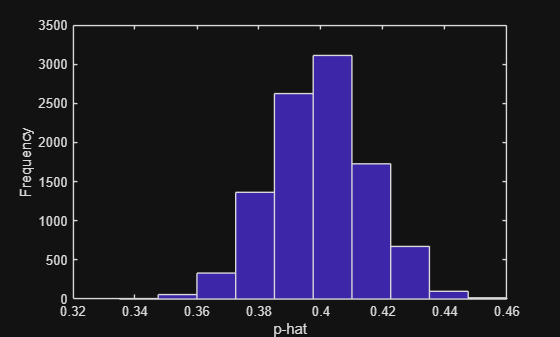

actualIgnitionProportion = 0.4;
numberTrials = 1e3;
numberReplications = 1e4;
ignitionSimulation = binornd(numberTrials, actualIgnitionProportion, numberReplications, 1);
sampleProportions = ignitionSimulation / numberTrials;

hist(sampleProportions)
xlabel("p-hat")
ylabel("Frequency")

mean(sampleProportions < R)

ans = 0.1161